clear all
format longG
u = symunit;

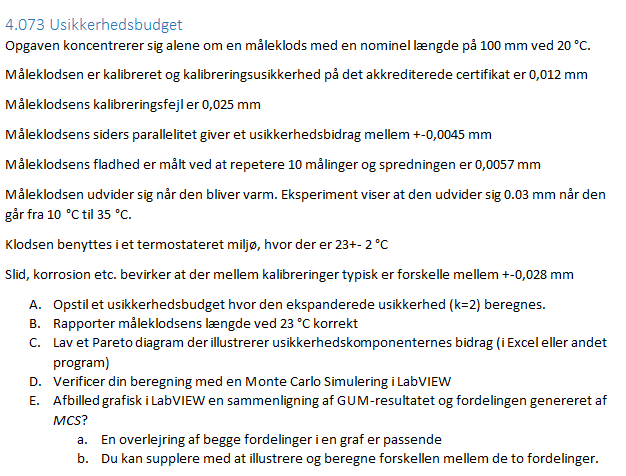

**Måleklodsen er kalibreret og kalibreringsusikkerhed på det akkrediterede certifikat er 0,012 mm**

**Måleklodsens kalibreringsfejl er 0,025 mm **-- Denne fejl kan være anderledes ved $23\degree C$.

Når der korrigeres for fejlen fås de $0,025 \pm 0,012 mm$. Dette ses som en type B usikkerhed der er normal fordelt da vi ikke kender antal målinger.

Da vi har en systematisk fejl kan vi korriger for fejlen.

Type: Kalibrering(udstyr) - **Systematisk**

k = 2; % Vi finder 95% konfidens
a = k; % Vi ser på vores grafer ud til hvor 95% af arealet ligge inden for vroes grænser.

Vi begynder nu at opstille tabellen og ser på hvert usikkerheds bidrag.

headings = {'Katogori', 'Beskrivelse', 'Symbol', 'Type', 'u_bidrag', 'Fordeling', 'Sider', 'Eakva_faktor', 'Folsomhed', 'n'};
kal_bidrag = ['Udstyr', "Kalibrering", 'delta_kal', 'B', 0.012*u.mm, 'Normal', 2, a/1, 1 * u.mm, inf]

$$kal\_bidrag = \left(\begin{array}{cccccccccc} \mathrm{Udstyr} & \mathrm{Kalibrering} & \delta_{\mathrm{kal}} & B & \frac{3}{250}\,\mathrm{mm} & \mathrm{Normal} & 2 & 2 & \mathrm{mm} & \infty \end{array}\right)$$

Da vi har type B usikkerhed antages uendelige antal målinger

**Måleklodsens siders parallelitet giver et usikkerhedsbidrag mellem +-0,0045 mm**

Dette ses som en type B usikkerheder med en firkantfordeling da der kan være afrundingsfejl. 

Type: Dimensionering(udstyr) - **Tilfældig**

par_bidrag = ['Udstyr', "Parallelitet", 'delta_par', 'B', 0.0045*u.mm, 'Firkant', 2, a/sqrt(3), 1*u.mm, inf]

$$par\_bidrag = \left(\begin{array}{cccccccccc} \mathrm{Udstyr} & \mathrm{Parallelitet} & \delta_{\mathrm{par}} & B & \frac{9}{2000}\,\mathrm{mm} & \mathrm{Firkant} & 2 & \frac{2\,\sqrt{3}}{3} & \mathrm{mm} & \infty \end{array}\right)$$

Da vi har type B usikkerhed antages uendelige antal målinger

**Måleklodsens fladhed er målt ved at repetere 10 målinger og spredningen er 0,0057 mm**

Dette anses som en type A usikkerhed da vi har 10 målinger og en spredning. Vores usikkerhed er derfor spredningen 0,0057 mm. Da der er få målinger benyttes også students t på målingerne.

Type: Dimensionering(udstyr) - **Tilfældig**

flad_bidrag = ['Udstyr', "Fladhed", 'delta_flad', 'A', 0.0057*u.mm, "Studentst", 1, a/1, 1*u.mm, 10]

$$flad\_bidrag = \left(\begin{array}{cccccccccc} \mathrm{Udstyr} & \mathrm{Fladhed} & \delta_{\mathrm{flad}} & A & \frac{57}{10000}\,\mathrm{mm} & \mathrm{Studentst} & 1 & 2 & \mathrm{mm} & 10 \end{array}\right)$$

**Måleklodsen udvider sig når den bliver varm. Eksperiment viser at den udvider sig 0.03 mm når den går fra 10 °C til 35 °C.**

**Klodsen benyttes i et termostateret miljø, hvor der er 23+- 2 °C**

**Slid, korrosion etc. bevirker at der mellem kalibreringer typisk er forskelle mellem +-0,028 m**

Vi interpolere lineært og finder forlængelsen ved $20 \degree C$ og $23 \degree C$  med hældningskonstanten $a = \frac{0.03}{35-10} = 0,0012\ mm/ \degree C$.


$$\delta_{varme,23} = T_{23} \cdot \frac{\Delta x_{10-35}}{T_{35} - T_{10}} $$


usikkerheden på temperaturen forventes trekants fordelt da det formådes der bruges en PID regulering til at holde temperaturen.

Usikkerheden på længden forventes firkant fordelt.

Udvidelsen af klodsen ses som en systematisk fejl og kan derfor udregnes og korigeres for.

Type: Miljø - **Systematisk**

Vi får således den samlede ligning


$$x_{m\aa l,str} = x_{vis} - (\delta_{kal} +  T_{23} \cdot \frac{\Delta x_{10-35}}{T_{35} - T_{10}} + \delta_{para} + \delta_{flade})$$


Det ses at alle $\delta$ får en vægtning på 1 og at vi bliver nød til at benytte ophobningsloven for varmeudvidelses bidraget. (se kode eksempel i bunden)

syms T_23 delta_x_1035 T_35 T_10
f_varm = T_23 * delta_x_1035  / (T_35 - T_10);

vars_and_u = [[T_23, 23, 2]; 
              [delta_x_1035,0.03 ,0.028]  
              [T_35, 35, 2]
              [T_10, 10, 2]];

[delta_x, u_varm] = STAT.Ophobningsloven_m(f_varm, vars_and_u) %uden enheder

0.02760000±0.02605932

delta_x =                     0.0276


u_varm =         0.0260593194078433


Vi kan nu opstille vores usikkerheds budget

varm_bidrag = ['Miljo', "Varmeudvidelse", 'delta_varm', 'B', u_varm*u.mm, 'Trekant', 2, a/1, delta_x*u.mm, inf]

$$varm\_bidrag = \left(\begin{array}{cccccccccc} \mathrm{Miljo} & \mathrm{Varmeudvidelse} & \delta_{\mathrm{varm}} & B & \frac{7511087435180285}{288230376151711744}\,\mathrm{mm} & \mathrm{Trekant} & 2 & 2 & \frac{69}{2500}\,\mathrm{mm} & \infty \end{array}\right)$$

Da vi har type B usikkerhed antages uendelige antal målinger

budget = [kal_bidrag; par_bidrag; flad_bidrag; varm_bidrag]; % vi udpakker navne for bedre overblik over tabellen
for i=1:size(headings, 2)
    var.(string(headings(i))) = budget(:,i);
end

T = table(var.Katogori, var.Beskrivelse, var.Symbol, var.Type, vpa(var.u_bidrag,3), var.Fordeling, var.Sider, vpa(var.Eakva_faktor,3), var.Folsomhed, var.n, ...
    'VariableNames',headings);

disp(T)

    Katogori     Beskrivelse        Symbol      Type     u_bidrag      Fordeling    Sider    Eakva_faktor      Folsomhed        n 
    ________    ______________    __________    ____    ___________    _________    _____    ____________    ______________    ___

     Udstyr     Kalibrering       delta_kal      B      0.012*[mm]     Normal         2          2.0         [mm]              Inf
     Udstyr     Parallelitet      delta_par      B      0.0045*[mm]    Firkant        2          1.15        [mm]              Inf
     Udstyr     Fladhed           delta_flad     A      0.0057*[mm]    Studentst      1          2.0         [mm]              10 
    

Std_usikkerhed = var.u_bidrag / var.Sider * var.Eakva_faktor; % u_bidrag / Sider * Eakva_faktor

Std_usikkerhed_ = vpa(Std_usikkerhed,3)

$$Std\_usikkerhed\_ = \left(\begin{array}{c} 0.012\,\mathrm{mm}\\ 0.0045\,\mathrm{mm}\\ 0.0057\,\mathrm{mm}\\ 0.0261\,\mathrm{mm} \end{array}\right)$$

u_komb = sum(Std_usikkerhed);

Den kombinered usikkerhed findes

u_komb_ = vpa(u_komb, 4)

$$u\_komb\_ = 0.04826\,\mathrm{mm}$$

v_eff = u_komb^4 / sum(Std_usikkerhed.^4./(budget(:,10)-1)); %Welch-Satterhwaite
v_eff_ = vpa(v_eff,8)

$$v\_eff\_ = 46245.327$$

t = tinv(0.95,double(separateUnits(v_eff))) % finder t værdien

t =           1.64488657730441


U_eksp = vpa(t * u_komb, 4) %den ekspanderede usikkerhed

$$U\_eksp = 0.07938\,\mathrm{mm}$$

Således fås målesklodsenslængde ukorrigerede til

$100,000 \pm 0,079$ **mm**

Vi kan korrigere for de systematiske fejl med


$$0,025 mm + 0,0276 mm = 0,053 mm$$


og dermed vill vi få 

$100,053 \pm 0,079$ **mm **

**OBS - ***her bør usikkerheden dog være anderledes og er i tvivl om hvordan man gøre forskel på den korrigerede og og korrigerede løsning.*

VI kan nu danne vores Pareto diagram

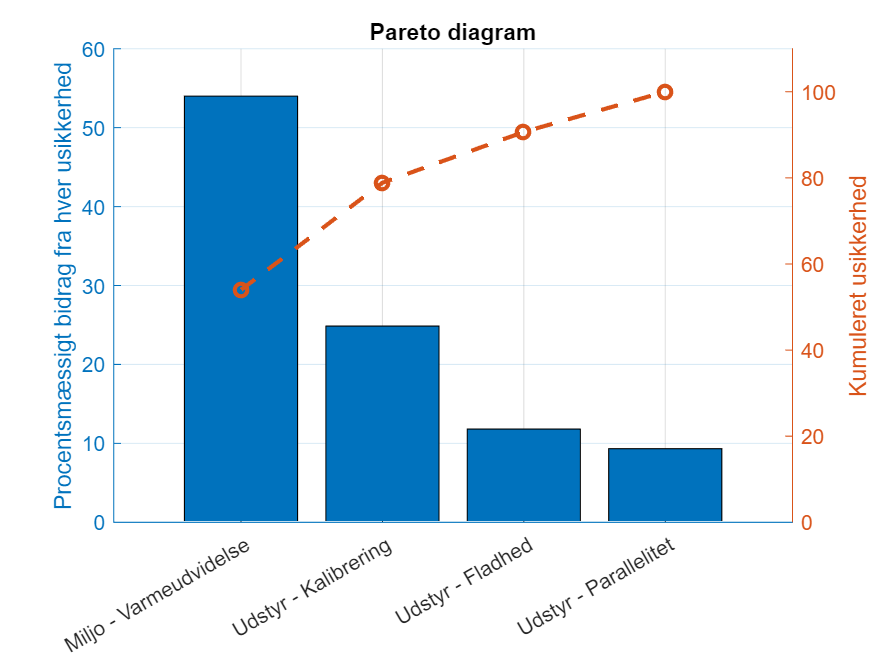

weight = vpa(Std_usikkerhed_./u_komb * 100',3); % vi vægter vores bedrag så de summer til 100 %
w = sort(weight,'descend'); %sortere listen
for i = 1:length(w)
    order = find(weight==w(i)); % finder ordenen af den sorterede liste
    sorting(i) = order;
    bar_names(i) = string(budget(order,1)) + ' - ' + string(budget(order,2)); %sortere tilhørende strings
end
bar_names_sort = reordercats(categorical(bar_names), bar_names); %sortere navne


clf
hold on
yyaxis left
ylabel("Procentsmæssigt bidrag fra hver usikkerhed")

bar(bar_names_sort, double(w))
title("Pareto diagram")
grid("on")

yyaxis right

for i = 1:length(w)
    ws(i) = sum(w(1:i,1));
end
plot(ws, '--o', linewidth=2)
ylabel("Kumuleret usikkerhed")
ylim([0,110])
hold off

# Der laves Monto carlo simulering i lab veiw

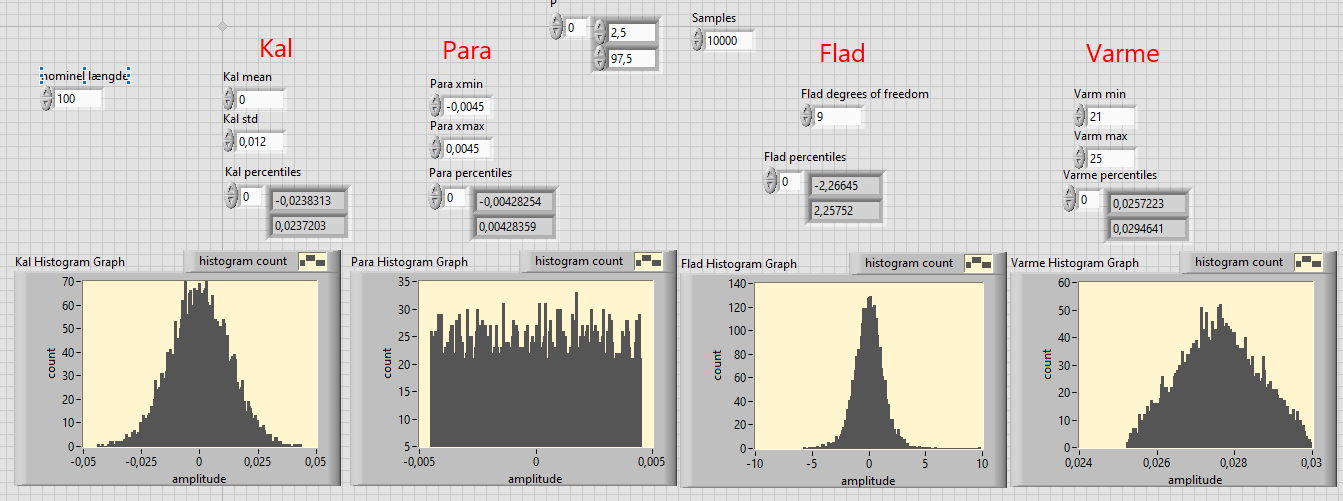

Vi ser at middel værdierne ligger inden for 95% confidens intervallet i alle 4 målinger og det ser ud til de beregnede usikkerhed også ligger indenfor.

Der hvor det passer dårligst er ved vores fladhed hvor vi godt kunne have ønsket en mindre spredning.

Vi sammenligner med vores GUM beregninger ved at sætte dem ind i et histogram sammen med de total beregninger fra monte carlo.

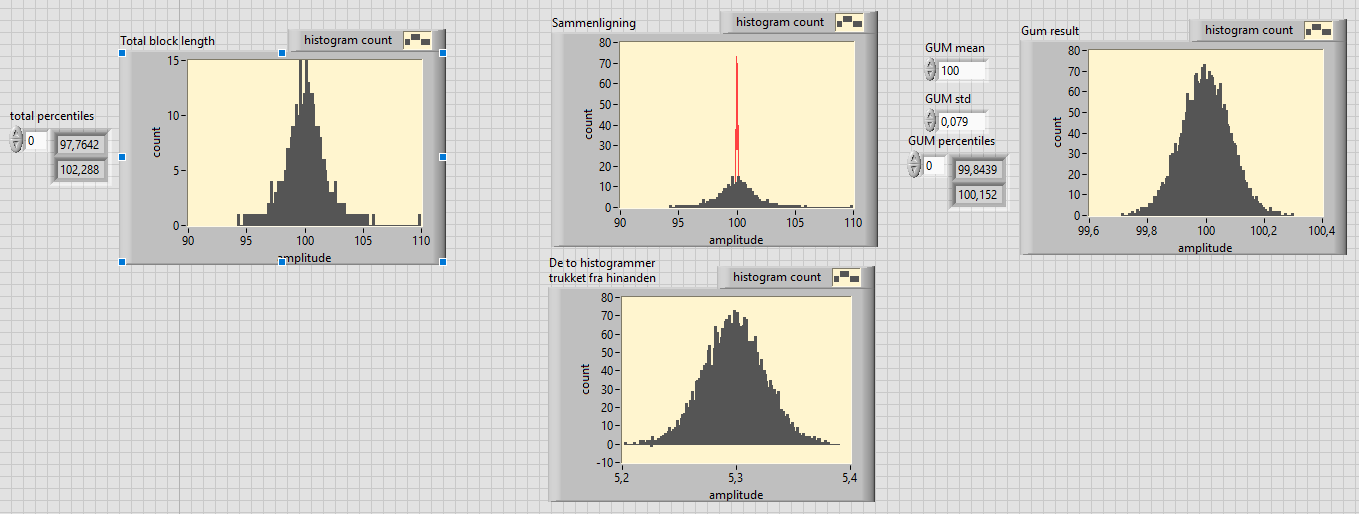

Vi ser således at Vores gum beregninger (rød) er meget mere præcise hvilket nok også skyldes den store spredning på fladheden i det simulerede.

Vi kan også se at når vi trækker MCS fra GUM fås residualer imellem 5,2 og 5,4 hvilket med flere kørsler rykker sig lidt, men altid er positivt.

Dette kunne indikere at montekarlo simuleringerne er en lille smule højre halet.